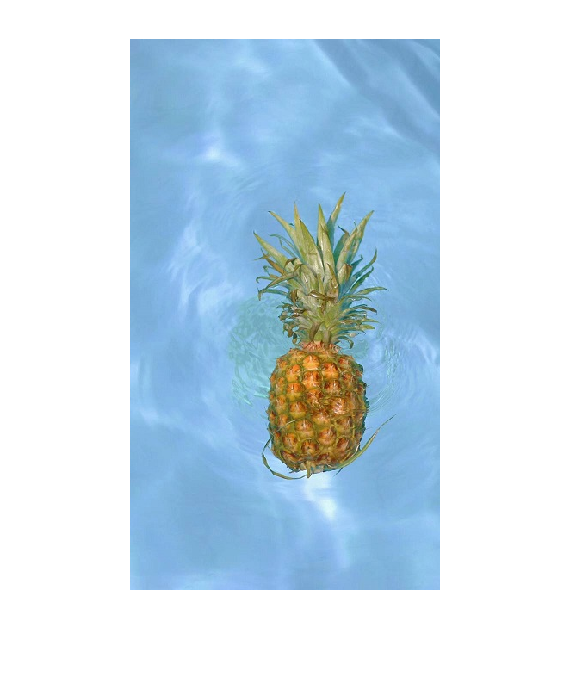

f=imread('./TestPhotos/fruits.jpg','jpg');
imshow(f);

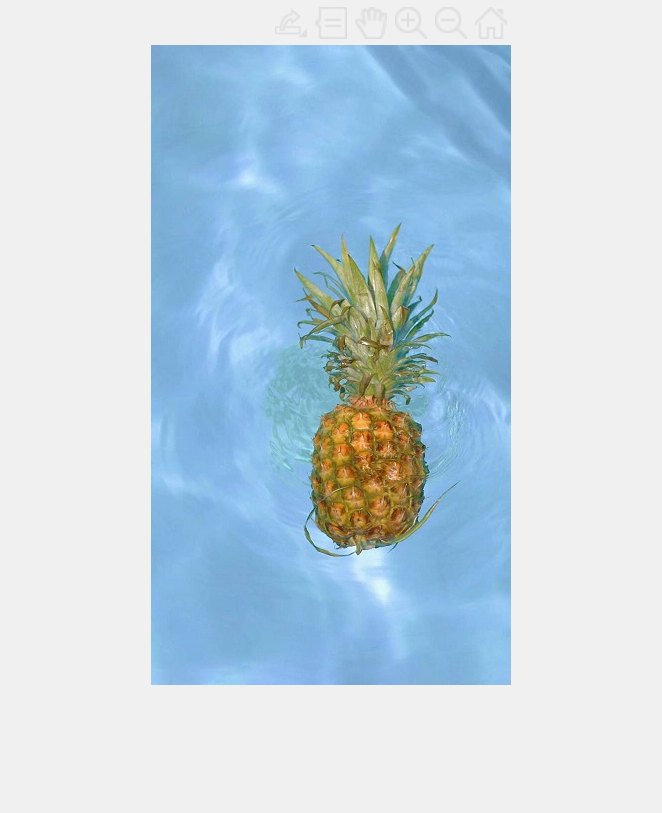

mask=roipoly(f); %采用交互式的方式提取感兴趣的区域ROI

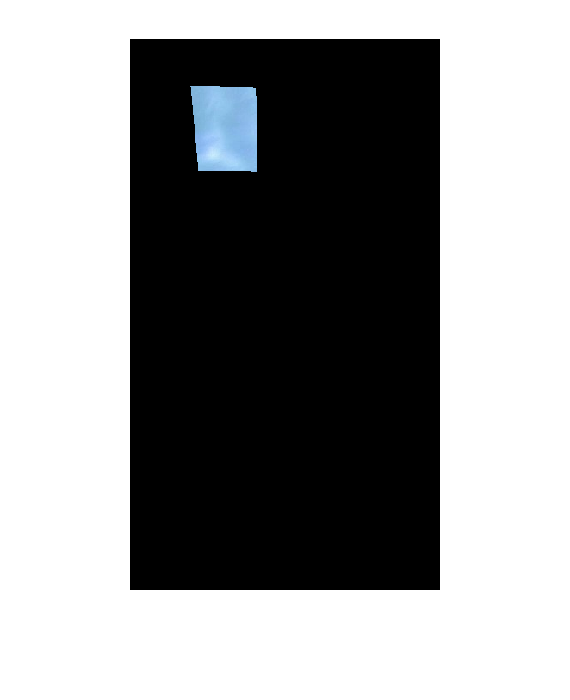

red=immultiply(mask, f(:, :, 1));
green=immultiply(mask, f(:, :, 2));
blue=immultiply(mask, f(:, :, 3));
g=cat(3, red, green, blue);
figure; imshow(g); %显示感兴趣的区域

 
[M, N, K]=size(g);
I=reshape(g, M*N, 3);
idx=find(mask);
I= double(I(idx, 1:3));
[C, m]=covmatrix(I); %计算ROI的协方差矩阵和均值
d=diag(C);
sd=sqrt(d); %计算ROI中RGB个分量的标准差
 
E25_o=colorseg('eclidean', f, 25, m) %25是根据最大标准差而取，通常为最大标准差的倍数。按照欧式距离计算

E25_o =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

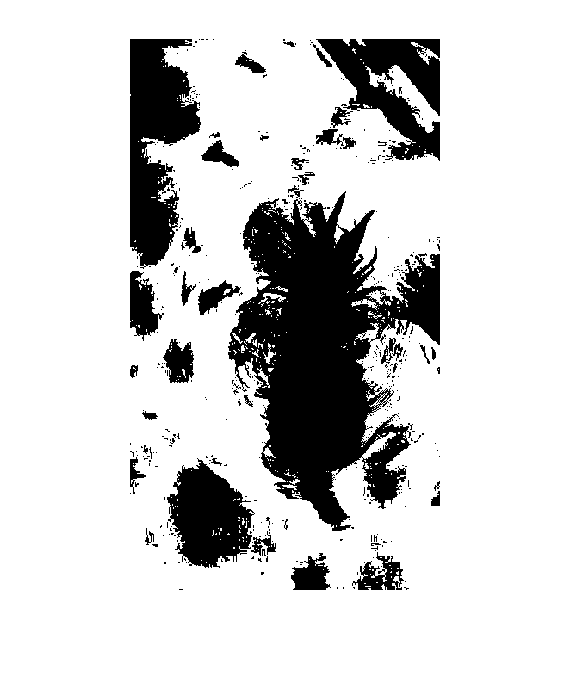

figure; imshow(E25_o);

 
E25_m=colorseg('mahalanobis', f, 25, m) %25是根据最大标准差而取，通常为最大标准差的倍数。按照马氏距离计算

E25_m =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

figure; imshow(E25_m)

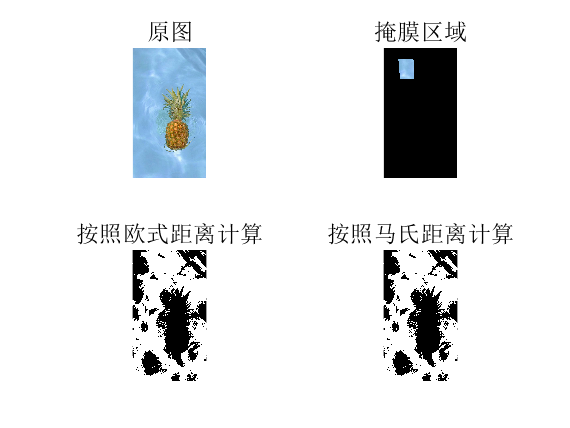


figure;
subplot(2,2,1)
imshow(f);title('原图')
subplot(2,2,2)
imshow(g);title('掩膜区域')
subplot(2,2,3)
imshow(E25_o);title('按照欧式距离计算')
subplot(2,2,4)
imshow(E25_m);title('按照马氏距离计算')